# Hobbing 2

## Definition

Modul?

m=3;

al_n= 20;
d_WZ= 40;

Zähnezahlen?

z_WZ= 1;
z_WST= 24;

h_f0f =1.4;
h_a0f= 1.17;

[phi_WZ,r_WZ,h_WZ] = WZ(d_WZ, m, al_n, h_a0f, h_f0f, z_WZ);
phi_WZ'

ans =      1.838711662108477e-02
     3.431413515549657e-03
    -3.431413515549657e-03
    -1.838711662108477e-02


r_WZ'

ans =      1.580000000000000e+01
     2.351000000000000e+01
     2.351000000000000e+01
     1.580000000000000e+01


h_WZ'

ans =     -3.873989158589616e+00
    -1.075637978412799e+00
     1.075637978412799e+00
     3.873989158589616e+00


X= m*z_WST/2 + d_WZ/2;
Y=0; 
Z=-5;
ga=0; Y_shift=0; a=0; b=0; c=0;
A= -atan2(m,d_WZ);
fX_WZrad=0; fY_WZrad=0; fZ_WZrad= -10/(2*pi);
fC_WSTrad= -1/z_WST;

## CAD Daten des Zahnrads

laden

gear.path = "D:\git\ba\scherbarth";
gear.name = "m3z24h10.stl";
m3z24h10 = stlread(fullfile(gear.path,gear.name));
x_WST= m3z24h10.Points(:,1);
y_WST= m3z24h10.Points(:,2);
z_WST= -m3z24h10.Points(:,3);

Soll z-Position

z_soll= -6;

#### Alternativ mit fzero

tic
B= fzero(@(B) Z - c + B*fZ_WZrad + sin(A)*(Y + Y_shift + B*fY_WZrad) + h_WZ(1,2)*sin(A) + cos(A)*r_WZ(1,2)*sin(B-phi_WZ(1,2)) - z_soll, pi);
toc

Elapsed time is 0.023674 seconds.


#### Alternativ: Schleife über asin

tic
B_0= pi*0.75;
B= phi_WZ + pi + asin((Z - c - z_soll + B_0*fZ_WZrad + sin(A)*(Y + Y_shift + B_0*fY_WZrad) + h_WZ*sin(A))./(r_WZ*cos(A)));
while sum(abs(B-B_0)) > 0.001
   B_0= B; 
   B=  phi_WZ + pi + asin((Z - c - z_soll + B_0*fZ_WZrad + sin(A)*(Y + Y_shift + B_0*fY_WZrad) + h_WZ*sin(A))./(r_WZ*cos(A)));
end
toc

Elapsed time is 0.012402 seconds.


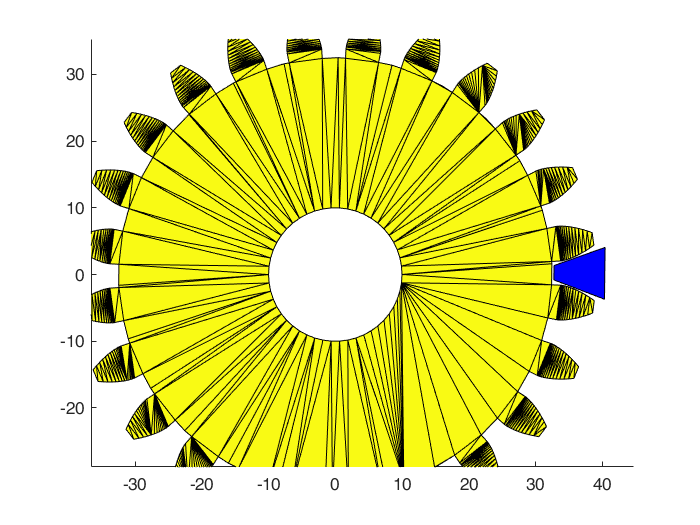

B=B(1,2);

x_WZm= X - a + B*fX_WZrad + cos(B)*r_WZ.*cos(phi_WZ) - sin(B)*r_WZ.*sin(phi_WZ); 
y_WZm= cos(A)*(Y + Y_shift + B*fY_WZrad) - b + h_WZ*cos(A) - sin(A)*cos(B)*r_WZ.*sin(phi_WZ) - sin(A)*sin(B)*r_WZ.*cos(phi_WZ); 
z_WZm= Z - c + B*fZ_WZrad + sin(A)*(Y + Y_shift + B*fY_WZrad) + h_WZ*sin(A) + cos(A)*r_WZ.*sin(B-phi_WZ);
clf; axis equal; hold on;
fill3(x_WZm', y_WZm', z_WZm','b')

x_WSTm= x_WST*cos(ga + B*fC_WSTrad) - y_WST*sin(ga + B*fC_WSTrad);
y_WSTm= x_WST*sin(ga + B*fC_WSTrad) + y_WST*cos(ga + B*fC_WSTrad);
z_WSTm= z_WST;
Zahnrad = triangulation(m3z24h10.ConnectivityList,x_WSTm(:),y_WSTm(:),z_WSTm(:));
trisurf(Zahnrad)